# **Dracula Tutorial**

close all
clear
clc
rng(0)

### **Basic Plots**

The syntax for making your figures Dracula themed is easy. Simply create a plot as you would normally and then call the function `draculize` with no inputs or outputs.

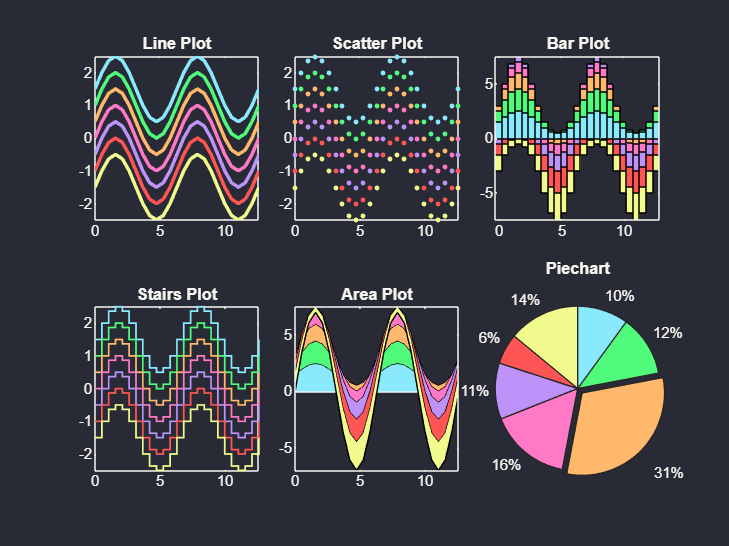

x = linspace(0,4*pi,25)';
y = ones(length(x),7) .* sin(x) + ...
    [1.5 1.0 0.5 0.0 -0.5 -1.0 -1.5];

figure(1)
tiledlayout(2,3,'TileSpacing','tight')
nexttile
 plot(x,y,'LineWidth',2), axis square tight
 title('Line Plot')
 draculize
nexttile
 scatter(x,y,8,'o','filled'), box on, axis square tight
 title('Scatter Plot')
 draculize
nexttile
 bar(x,y,1,'stacked'), axis square tight
 title('Bar Plot')
 draculize
nexttile
 stairs(x,y,'LineWidth',1), axis square tight
 title('Stairs Plot')
 draculize
nexttile
 area(x,y), axis square tight
 title('Area Plot')
 draculize
nexttile
 piechart([10 12 31 16 11 6 14],'FaceAlpha',1,ExplodedW=3)
 title('Piechart')
 draculize

The `draculize` function also works on any basic plots that contain a title, subtitle, axes labels, a legend, added text, and grid lines. It also works for 3D plots.

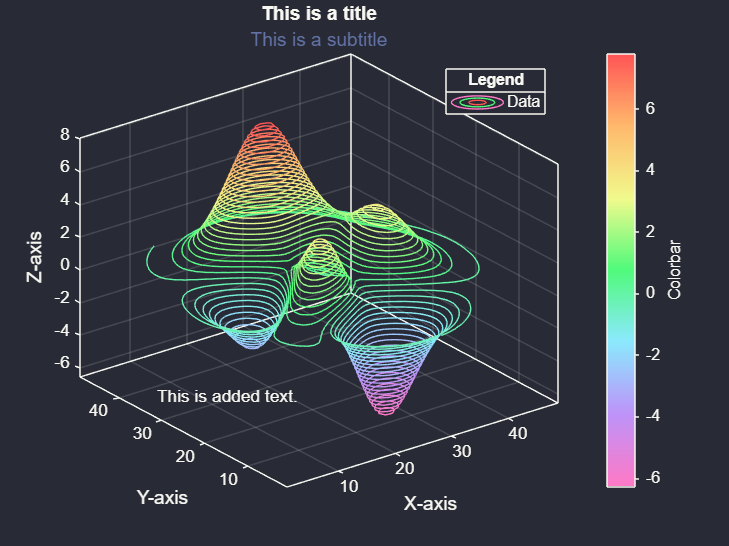

figure(2)
contour3(peaks,50)
 title('This is a title'), subtitle('This is a subtitle')
 xlabel('X-axis'), ylabel('Y-axis'), zlabel('Z-axis')
 hold on
    text(0,30,-5,'This is added text.')
 hold off
 grid on
 L=legend('Data','Location','northeast'); L.Title.String='Legend';
 cb=colorbar; cb.Label.String='Colorbar';
draculize

Note that if you add a label, legend, etc. *after* executing the `draculize` function, the new object(s) will not be automatically incorporated into the Dracula theme. You will need to call the `draculize` function again in order to update the figure.

### Optional input

Set the `AxesOnly` name-value pair to `true` to update the color theme of the axes but keep the current color order and color map.

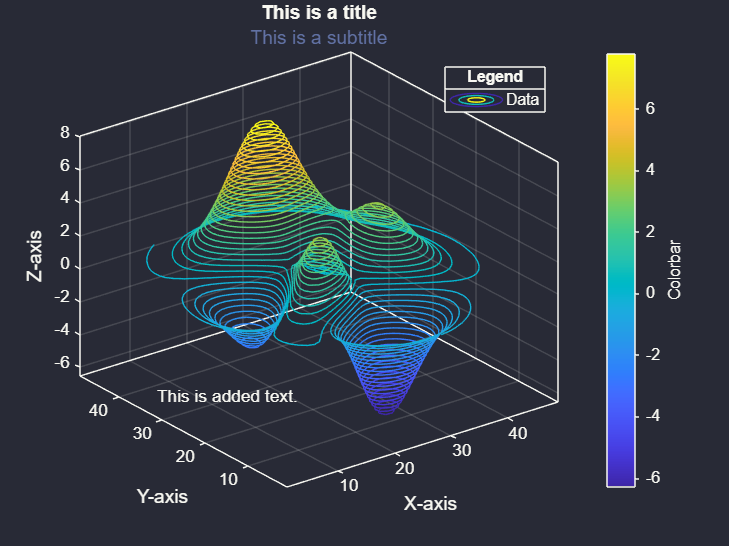

figure(3)
contour3(peaks,50)
 title('This is a title'), subtitle('This is a subtitle')
 xlabel('X-axis'), ylabel('Y-axis'), zlabel('Z-axis')
 hold on
    text(0,30,-5,'This is added text.')
 hold off
 grid on
 L=legend('Data','Location','northeast'); L.Title.String='Legend';
 cb=colorbar; cb.Label.String='Colorbar';
draculize(AxesOnly=true)

### **Color Order**

If you don't want to convert the entire figure into the Dracula theme, but want to use Dracula colors for your data, then call the function `dracula_colororder` after creating your plot.

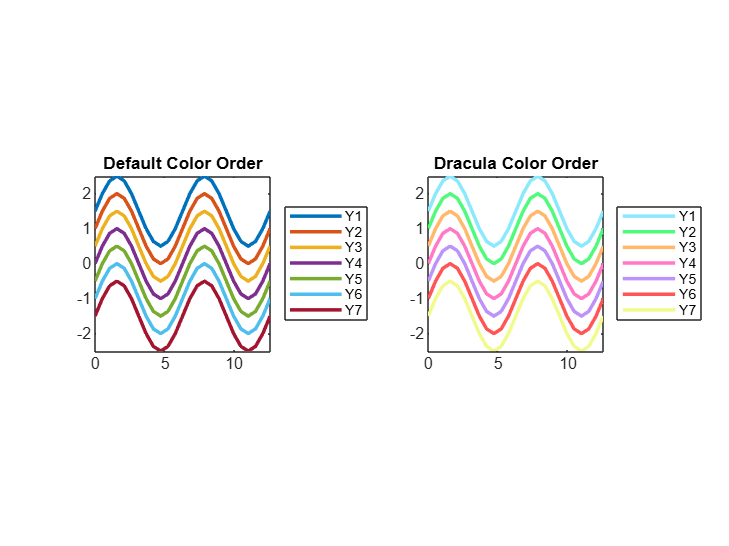

figure(4)
tiledlayout(1,2)
nexttile
 plot(x,y,'LineWidth',2), axis square tight
 title('Default Color Order')
 legend('Y1','Y2','Y3','Y4','Y5','Y6','Y7',...
     'Location','eastoutside')
nexttile
 plot(x,y,'LineWidth',2), axis square tight
 title('Dracula Color Order')
 legend('Y1','Y2','Y3','Y4','Y5','Y6','Y7',...
     'Location','eastoutside')
 dracula_colororder

Use optional name-value pairs to change the sequence of the color order and/or to limit the number of colors. For example:

`>> ``dracula_colororder``(Style='rainbow', Order='reverse', N=4)`

### **Color Map**

A custom Dracula-themed color map (`dracula_cmap`) is available in the `dracula.mat` binary file. This color map is automatically applied to a figure when using the `draculize` function. However, if they user *only* wants to use the color map without applying the full Dracula theme to a figure then simply call the `dracula_colormap` function!

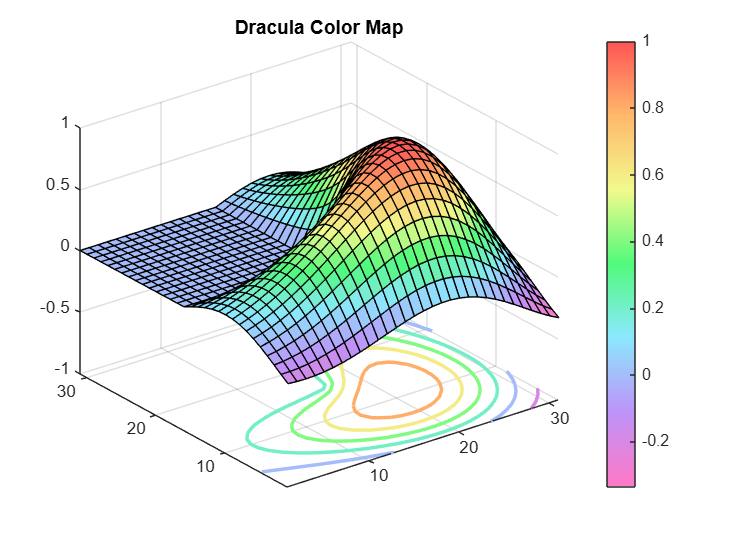

figure(5)
sc = surfc(membrane); sc(2).LineWidth=2; zlim([-1 1])
title('Dracula Color Map')
colorbar
dracula_colormap

You can flip the order of the Dracula color map by specifying the `Order='reverse'` name-value pair:

`>> ``dracula_colormap``(Order='reverse')`

### **Boxcharts and Histograms**

Boxcharts only display as one color, unless you have grouped data. The same is true for histograms. In either case, the `draculize` function still works. 

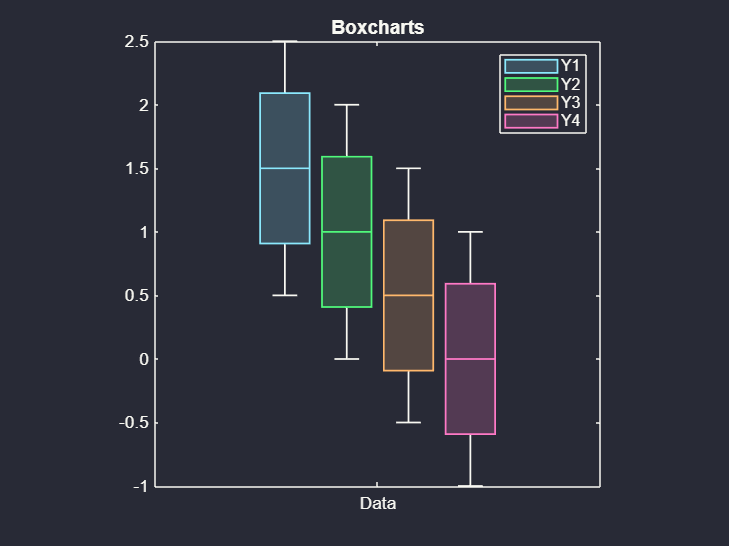

sz=size(y(:,1));
grp = [repmat("Y1",sz);...
       repmat("Y2",sz);...
       repmat("Y3",sz);...
       repmat("Y4",sz)];
data = table(categorical(grp), [y(:,1); y(:,2); y(:,3); y(:,4)],...
    'VariableNames',{'Group','Values'});
figure(6)
boxchart(data.Values,'GroupByColor',data.Group,'BoxWidth',0.8), box on, axis square
title('Boxcharts')
legend(categories(data.Group))
xticklabels('Data')
draculize

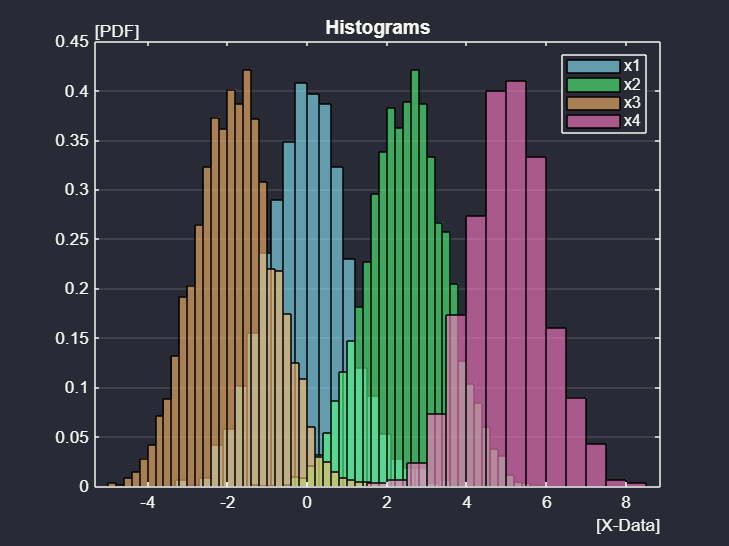

figure(7)
x1 = randn(2000,1);
x2 = 2.5 + randn(5000,1);
x3 = randn(3000,1) - 1.8;
x4 = randn(600,1) + 5;
h1 = histogram(x1,'Normalization','pdf');
title('Histograms')
hold on
 h2 = histogram(x2,'Normalization','pdf');
 h3 = histogram(x3,'Normalization','pdf');
 h4 = histogram(x4,'Normalization','pdf');
legend('x1','x2','x3','x4')
hold off
set(gca,'YGrid','on')
ysecondarylabel('[PDF]'), xsecondarylabel('[X-Data]')
draculize

### **Polar Axes Charts**

The `draculize` function is also compatible with charts generated in polar coordinates!

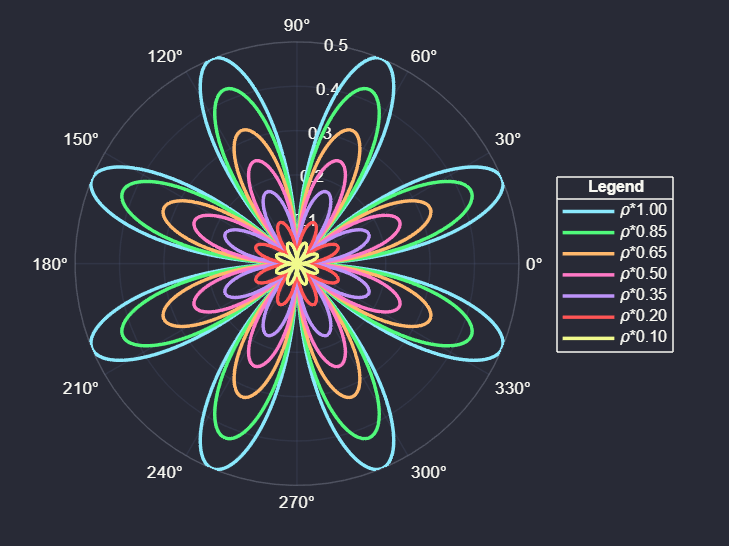

figure(8)
lw=2;
theta = 0:0.01:2*pi;
rho = sin(2*theta).*cos(2*theta);
 for i = 1:7
   j = [1.00 0.85 0.65 0.50 0.35 0.20 0.10];
   polarplot(theta,rho.*j(i),'LineWidth',lw)
   hold on
 end
hold off
leg = repmat("\rho*",[7 1]) + string(num2str(j','%0.2f'));
L2=legend(leg); L2.Title.String='Legend';
draculize